# 1、船只信息（不带重物和桅杆）

boat.L = 0.30 %长，单位m

boat = 包含以下字段的 struct :
          L: 0.3000
         HL: 0.1600
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


boat.HL = boat.L/2;

boat.W = 0.16 %宽，单位m

boat = 包含以下字段的 struct :
          L: 0.3000
         HL: 0.1500
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


boat.HW = boat.W/2;

boat.D = 0.12 %高，单位m

boat = 包含以下字段的 struct :
          L: 0.3000
         HL: 0.1500
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 135
    include: [321×161×121 logical]
          v: 0.0031
        rho: 59.7553


boat.HD = boat.D/2;

boat.mass = 0.1847; %考虑船只所切割木板利用率仅为70%，而且船只为均质的

boat.theta = 20; %倾斜角度
A=boat.D/boat.HW^4;
B=boat.D/boat.HL^2;
% z=1000*x^4+2.5*y^2

# 2、桅杆信息

weigan.mass = 0.107; %单位kg 

weigan.r = 0.005; %单位m

weigan.L = 0.5;

# 3、重物信息

zhongwu.mass = 0.85; %单位kg

zhongwu.com = 0.04;

zhongwu.L = 0.; %单位m
zhongwu.HL = zhongwu.L/2;

zhongwu.r = 0.02;

dx = 0.001;
dy = 0.001;
dz = 0.001;

# 船的微元及体积、质量微元表示

mesh.x = -boat.HW:dx:boat.HW;%创建一个 x 坐标向量，从 -boat.HW 开始，以步长 dx 递增，直到 boat.HW
mesh.y = -boat.HL:dy:boat.HL;%创建一个y坐标向量，cong-boat.HL开始，以步长 dy 递增，直到boat.HL
mesh.z = 0:dz:boat.D;%创建一个 z 坐标向量，从 0 开始，以步长 dz 递增，直到 boat.D
[mesh.xgrid,mesh.ygrid,mesh.zgrid] = meshgrid(mesh.x,mesh.y,mesh.z)%使用 mesh.x、mesh.y 和 mesh.z 中的坐标向量创建一个三维网格，其中 mesh.xgrid、mesh.ygrid 和 mesh.zgrid 分别为三个坐标轴上的网格点坐标

mesh = 包含以下字段的 struct :
        x: [-0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 -0.0720 -0.0710 -0.0700 -0.0690 -0.0680 -0.0670 -0.0660 -0.0650 -0.0640 -0.0630 -0.0620 -0.0610 -0.0600 -0.0590 -0.0580 -0.0570 -0.0560 -0.0550 -0.0540 -0.0530 -0.0520 … ]
        y: [-0.1500 -0.1490 -0.1480 -0.1470 -0.1460 -0.1450 -0.1440 -0.1430 -0.1420 -0.1410 -0.1400 -0.1390 -0.1380 -0.1370 -0.1360 -0.1350 -0.1340 -0.1330 -0.1320 -0.1310 -0.1300 -0.1290 -0.1280 -0.1270 -0.1260 -0.1250 -0.1240 -0.1230 -0.1220 … ]
        z: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 … ]
    xgrid: [301×161×121 double]
    ygrid: [301×161×121 double]
    zgrid: [301×161×121 double]
       dv: 1.0000e-09


mesh = 包含以下字段的 struct :
        x: [-0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 -0.0720 -0.0710 -0.0700 -0.0690 -0.0680 -0.0670 -0.0660 -0.0650 -0.0640 -0.0630 -0.0620 -0.0610 -0.0600 -0.0590 -0.0580 -0.0570 -0.0560 -0.0550 -0.0540 -0.0530 -0.0520 … ]
        y: [-0.1500 -0.1490 -0.1480 -0.1470 -0.1460 -0.1450 -0.1440 -0.1430 -0.1420 -0.1410 -0.1400 -0.1390 -0.1380 -0.1370 -0.1360 -0.1350 -0.1340 -0.1330 -0.1320 -0.1310 -0.1300 -0.1290 -0.1280 -0.1270 -0.1260 -0.1250 -0.1240 -0.1230 -0.1220 … ]
        z: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 … ]
    xgrid: [301×161×121 double]
    ygrid: [301×161×121 double]
    zgrid: [301×161×121 double]
       dv: 1.0000e-09


mesh = 包含以下字段的 struct :
        x: [-0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 -0.0720 -0.0710 -0.0700 -0.0690 -0.0680 -0.0670 -0.0660 -0.0650 -0.0640 -0.0630 -0.0620 -0.0610 -0.0600 -0.0590 -0.0580 -0.0570 -0.0560 -0.0550 -0.0540 -0.0530 -0.0520 … ]
        y: [-0.1500 -0.1490 -0.1480 -0.1470 -0.1460 -0.1450 -0.1440 -0.1430 -0.1420 -0.1410 -0.1400 -0.1390 -0.1380 -0.1370 -0.1360 -0.1350 -0.1340 -0.1330 -0.1320 -0.1310 -0.1300 -0.1290 -0.1280 -0.1270 -0.1260 -0.1250 -0.1240 -0.1230 -0.1220 … ]
        z: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 … ]
    xgrid: [301×161×121 double]
    ygrid: [301×161×121 double]
    zgrid: [301×161×121 double]
       dv: 1.0000e-09



boat.include = includeBoat(mesh,boat)%调用 includeBoat 函数，将 mesh 和 boat 作为参数传递，计算出船体区域的逻辑掩码，将结果存储在 boat.include 中

boat = 包含以下字段的 struct :
          L: 0.3000
         HL: 0.1500
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 20
    include: [301×161×121 logical]
          v: 0.0031
        rho: 59.7553


mesh.dv = dx * dy * dz%计算微元体积，即每个黎曼和立方体的体积，通过将步长 dx、dy 和 dz 相乘得到

mesh = 包含以下字段的 struct :
        x: [-0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 -0.0720 -0.0710 -0.0700 -0.0690 -0.0680 -0.0670 -0.0660 -0.0650 -0.0640 -0.0630 -0.0620 -0.0610 -0.0600 -0.0590 -0.0580 -0.0570 -0.0560 -0.0550 -0.0540 -0.0530 -0.0520 … ]
        y: [-0.1500 -0.1490 -0.1480 -0.1470 -0.1460 -0.1450 -0.1440 -0.1430 -0.1420 -0.1410 -0.1400 -0.1390 -0.1380 -0.1370 -0.1360 -0.1350 -0.1340 -0.1330 -0.1320 -0.1310 -0.1300 -0.1290 -0.1280 -0.1270 -0.1260 -0.1250 -0.1240 -0.1230 -0.1220 … ]
        z: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 … ]
    xgrid: [301×161×121 double]
    ygrid: [301×161×121 double]
    zgrid: [301×161×121 double]
       dv: 1.0000e-09


total_cube = sum(sum(sum(boat.include)))%计算船体区域内的立方体数量，通过对 boat.include 中的所有元素求和得到

total_cube = 2897204

boat.v = total_cube * mesh.dv%计算船体的总质量

boat = 包含以下字段的 struct :
          L: 0.3000
         HL: 0.1500
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 20
    include: [301×161×121 logical]
          v: 0.0029
        rho: 59.7553


boat.rho = boat.mass / boat.v%计算船体的密度

boat = 包含以下字段的 struct :
          L: 0.3000
         HL: 0.1500
          W: 0.1600
         HW: 0.0800
          D: 0.1200
         HD: 0.0600
       mass: 0.1847
      theta: 20
    include: [301×161×121 logical]
          v: 0.0029
        rho: 63.7511


mass_per_cube = mesh.dv * boat.rho  %每个黎曼和立方体质量

mass_per_cube = 6.3751e-08

boat_M_3 = boat.include * mass_per_cube  %整个船的质量三维数组

boat_M_3 = boat_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   

boat_M = sum(boat_M_3(:))%计算整个船体的总质量，通过对 boat_M_3 中的所有元素进行求和得到

boat_M = 0.1847

# 重物的微元及体积、质量微元表示

meshzhongwu.x = -zhongwu.r:dx:zhongwu.r;%创建一个 x 坐标向量，从 -zhongwu.r 开始，以步长 dx 递增，直到 zhongwu.r
meshzhongwu.y = -zhongwu.HL:dy:zhongwu.HL;
meshzhongwu.z = 0.00:dz:0.04;

[meshz.xgrid,meshz.ygrid,meshz.zgrid] = meshgrid(meshzhongwu.x,meshzhongwu.y,meshzhongwu.z)%使用 meshzhongwu.x、meshzhongwu.y 和 meshzhongwu.z 中的坐标向量创建一个三维网格，其中 mesh.xgrid、mesh.ygrid 和 mesh.zgrid 分别为三个坐标轴上的网格点坐标

meshz = 包含以下字段的 struct :
    xgrid: [1×41×41 double]
    ygrid: [1×41×41 double]
    zgrid: [1×41×41 double]
       dv: 1.0000e-09


meshz = 包含以下字段的 struct :
    xgrid: [1×41×41 double]
    ygrid: [1×41×41 double]
    zgrid: [1×41×41 double]
       dv: 1.0000e-09


meshz = 包含以下字段的 struct :
    xgrid: [1×41×41 double]
    ygrid: [1×41×41 double]
    zgrid: [1×41×41 double]
       dv: 1.0000e-09



zhongwu.include = includezhongwu(meshz)%调用 includezhongwu 函数，将 mesh 和 zhongwu 作为参数传递，计算出船体区域的逻辑掩码，将结果存储在 zhongwu.include 中

zhongwu = 包含以下字段的 struct :
       mass: 0.8500
        com: 0.0400
          L: 0
         HL: 0
          r: 0.0200
    include: [1×41×41 logical]
          v: 1.0353e-04
        rho: 6.7617e+03


meshz.dv = dx * dy * dz%计算微元体积，即每个黎曼和立方体的体积，通过将步长 dx、dy 和 dz 相乘得到

meshz = 包含以下字段的 struct :
    xgrid: [1×41×41 double]
    ygrid: [1×41×41 double]
    zgrid: [1×41×41 double]
       dv: 1.0000e-09


total_zhongwu_cube = sum(sum(sum(zhongwu.include)))%计算船体区域内的立方体数量，通过对 zhongwu.include 中的所有元素求和得到

total_zhongwu_cube = 646

zhongwu.v = total_zhongwu_cube * meshz.dv%计算船体的总质量

zhongwu = 包含以下字段的 struct :
       mass: 0.8500
        com: 0.0400
          L: 0
         HL: 0
          r: 0.0200
    include: [1×41×41 logical]
          v: 6.4600e-07
        rho: 6.7617e+03


zhongwu.rho = zhongwu.mass / zhongwu.v%计算船体的密度

zhongwu = 包含以下字段的 struct :
       mass: 0.8500
        com: 0.0400
          L: 0
         HL: 0
          r: 0.0200
    include: [1×41×41 logical]
          v: 6.4600e-07
        rho: 1.3158e+06


zhongwumass_per_cube = meshz.dv * zhongwu.rho  %每个黎曼和立方体质量

zhongwumass_per_cube = 0.0013

zhongwu_M_3 = zhongwu.include * zhongwumass_per_cube  %质量三维数组

zhongwu_M_3 = zhongwu_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


zhongwu_M_3(:,:,2) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


zhongwu_M_3(:,:,3) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


zhongwu_M_3(:,:,4) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

zhongwu_M = sum(zhongwu_M_3(:))%计算整个船体的总质量，通过对 zhongwu_M_3 中的所有元素进行求和得到

zhongwu_M = 0.8500

# 桅杆的微元及体积、质量微元表示

meshweigan.x = -weigan.r:dx:weigan.r;
meshweigan.y = -weigan.r:dy:weigan.r;
meshweigan.z = 0.05:dz:0.55;

[meshw.xgrid,meshw.ygrid,meshw.zgrid] = meshgrid(meshweigan.x,meshweigan.y,meshweigan.z)

meshw = 包含以下字段的 struct :
    xgrid: [11×11×501 double]
    ygrid: [11×11×501 double]
    zgrid: [11×11×501 double]
       dv: 1.0000e-09


meshw = 包含以下字段的 struct :
    xgrid: [11×11×501 double]
    ygrid: [11×11×501 double]
    zgrid: [11×11×501 double]
       dv: 1.0000e-09


meshw = 包含以下字段的 struct :
    xgrid: [11×11×501 double]
    ygrid: [11×11×501 double]
    zgrid: [11×11×501 double]
       dv: 1.0000e-09



weigan.include = includeweigan(meshw,weigan)

weigan = 包含以下字段的 struct :
       mass: 0.1070
          r: 0.0050
          L: 0.5000
    include: [11×11×501 logical]
          v: 3.8577e-05
        rho: 2.7737e+03


meshw.dv = dx * dy * dz

meshw = 包含以下字段的 struct :
    xgrid: [11×11×501 double]
    ygrid: [11×11×501 double]
    zgrid: [11×11×501 double]
       dv: 1.0000e-09


total_weigan_cube = sum(sum(sum(weigan.include)))

total_weigan_cube = 38577

weigan.v = total_weigan_cube * meshw.dv

weigan = 包含以下字段的 struct :
       mass: 0.1070
          r: 0.0050
          L: 0.5000
    include: [11×11×501 logical]
          v: 3.8577e-05
        rho: 2.7737e+03


weigan.rho = weigan.mass / weigan.v

weigan = 包含以下字段的 struct :
       mass: 0.1070
          r: 0.0050
          L: 0.5000
    include: [11×11×501 logical]
          v: 3.8577e-05
        rho: 2.7737e+03


weiganmass_per_cube = meshw.dv * weigan.rho  %每个黎曼和立方体质量

weiganmass_per_cube = 2.7737e-06

weigan_M_3 = weigan.include * weiganmass_per_cube  %质量三维数组

weigan_M_3 = weigan_M_3(:,:,1) =

   1.0e-05 *

         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    

weigan_M = sum(weigan_M_3(:))

weigan_M = 0.1070

# 总质量

total_masses = boat_M + zhongwu_M + weigan_M %带重物和桅杆的总质量

total_masses = 1.1417

chishui_v = total_masses / 1000 %吃水体积理论值

chishui_v = 0.0011

# 吃水线（为计算C，计算COM、COB时可以将它注释掉）

% %{
for C=0.06:0.001:0.107 %精度可调,变量 C 的取值范围从 0.06 开始，以 0.01 为步长递增，直到 0.107
    hullwater = includeWater(C,0,mesh); %倾斜角度可调，以确定C的值,调用 includeWater 函数，将 C、130 和 mesh 作为参数传递，计算出吃水区域的逻辑掩码，并将结果存储在 hullwater 中
    hull = boat.include & hullwater;%将船体区域的逻辑掩码 boat.include 与吃水区域的逻辑掩码 hullwater 进行逻辑与运算，得到船体浸水的部分的逻辑掩码，并将结果存储在 hull 中
    dv = dx * dy * dz;
    hullcube = sum(sum(sum(hull)));%计算船体浸水部分的立方体数量，通过对 hull 中的所有元素求和得到
    v = hullcube * dv;%计算船体浸水部分的体积，通过将立方体数量乘以微元体积得到
    m = v*1000 - 0.294
    fprintf('C = %f, m = %f\n',C,v);%打印输出结果，显示当前的 C 值和对应的
end

m = 0.5485

C = 0.060000, m = 0.000843


m = 0.5987

C = 0.061000, m = 0.000893


m = 0.6243

C = 0.062000, m = 0.000918


m = 0.6243

C = 0.063000, m = 0.000918


m = 0.6501

C = 0.064000, m = 0.000944


m = 0.6763

C = 0.065000, m = 0.000970


m = 0.7028

C = 0.066000, m = 0.000997


m = 0.7296

C = 0.067000, m = 0.001024


m = 0.7841

C = 0.068000, m = 0.001078


m = 0.8118

C = 0.069000, m = 0.001106


m = 0.8118

C = 0.070000, m = 0.001106


m = 0.8398

C = 0.071000, m = 0.001134


m = 0.8681

C = 0.072000, m = 0.001162


m = 0.8967

C = 0.073000, m = 0.001191


m = 0.9256

C = 0.074000, m = 0.001220


m = 0.9548

C = 0.075000, m = 0.001249


m = 0.9843

C = 0.076000, m = 0.001278


m = 1.0442

C = 0.077000, m = 0.001338


m = 1.0745

C = 0.078000, m = 0.001369


m = 1.1052

C = 0.079000, m = 0.001399


m = 1.1361

C = 0.080000, m = 0.001430


m = 1.1674

C = 0.081000, m = 0.001461


m = 1.1674

C = 0.082000, m = 0.001461


m = 1.1989

C = 0.083000, m = 0.001493


m = 1.2306

C = 0.084000, m = 0.001525


m = 1.2628

C = 0.085000, m = 0.001557


m = 1.2952

C = 0.086000, m = 0.001589


m = 1.3278

C = 0.087000, m = 0.001622


m = 1.3608

C = 0.088000, m = 0.001655


m = 1.3940

C = 0.089000, m = 0.001688


m = 1.4276

C = 0.090000, m = 0.001722


m = 1.4614

C = 0.091000, m = 0.001755


m = 1.4955

C = 0.092000, m = 0.001789


m = 1.5298

C = 0.093000, m = 0.001824


m = 1.5645

C = 0.094000, m = 0.001858


m = 1.5994

C = 0.095000, m = 0.001893


m = 1.6346

C = 0.096000, m = 0.001929


m = 1.6701

C = 0.097000, m = 0.001964


m = 1.7059

C = 0.098000, m = 0.002000


m = 1.7782

C = 0.099000, m = 0.002072


m = 1.8148

C = 0.100000, m = 0.002109


m = 1.8517

C = 0.101000, m = 0.002146


m = 1.8888

C = 0.102000, m = 0.002183


m = 1.9262

C = 0.103000, m = 0.002220


m = 1.9262

C = 0.104000, m = 0.002220


m = 1.9639

C = 0.105000, m = 0.002258


m = 2.0019

C = 0.106000, m = 0.002296


m = 2.0400

C = 0.107000, m = 0.002334



% }
% 
% fun = @(d) (findMassDiff(d,boat,mesh,zhongwu,weigan));
% depth = fzero(fun,0.0011515)
% 

# COM

COMboat = COM_boat(boat_M_3,mesh)%计算船的质心

COMboat =    -0.0000    0.0000    0.0767


COMzhongwu = COM_zhongwu(zhongwu_M_3,meshz)%计算重物的质心

COMzhongwu =    -0.0000         0    0.0318


COMweigan = COM_weigan(weigan_M_3,meshw)%计算桅杆的质心

COMweigan =     0.0000   -0.0000    0.3000


COM = (boat_M * COMboat + zhongwu_M * COMzhongwu + weigan_M * COMweigan) / total_masses %总质心

COM =    -0.0000    0.0000    0.0642


# COB

吃水部分表示

hullwater = includeWater(0.094,boat.theta,mesh); %吃水线区域07
hullwaterz = includeWaterz(0.094,boat.theta,meshz); 
hullwaterw = includeWaterw(0.094,boat.theta,meshw); 

船体

hullboatwater = boat.include & hullwater %船体浸在水中的部分 hullboatwater

hullboatwater = 301×161×121 logical 数组
hullboatwater(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

boatwater_M_3 = hullboatwater * mass_per_cube%船体浸没在水中的部分 hullboatwater 乘以 mass_oer_cube（每个黎曼和立方体的质量）

boatwater_M_3 = boatwater_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

COB_V.boatB_M = sum(boatwater_M_3(:)) %质量，单位kg

COB_V = 包含以下字段的 struct :
       boatB_M: 0.1226
    zhongwuB_M: 0.8500
     weiganB_M: 0.0095


重物

hullzhongwuwater = zhongwu.include & hullwaterz %重物浸在水中的部分 hullzhongwuwater

hullzhongwuwater = 1×41×41 logical 数组
hullzhongwuwater(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


hullzhongwuwater(:,:,2) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


hullzhongwuwater(:,:,3) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


hullzhongwuwater(:,:,4) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


hullzhongwuwater(:,:,5) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

zhongwuwater_M_3 = hullzhongwuwater * zhongwumass_per_cube

zhongwuwater_M_3 = zhongwuwater_M_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


zhongwuwater_M_3(:,:,2) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


zhongwuwater_M_3(:,:,3) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


zhongwuwater_M_3(:,:,4) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

COB_V.zhongwuB_M = sum(zhongwuwater_M_3(:)) %质量，单位kg

COB_V = 包含以下字段的 struct :
       boatB_M: 0.1226
    zhongwuB_M: 0.8500
     weiganB_M: 0.0095


桅杆

hullweiganwater = weigan.include & hullwaterw %桅杆浸在水中的部分 hullweiganwater

hullweiganwater = 11×11×501 logical 数组
hullweiganwater(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0
   0   0   1   1   1   1   1   1   1   0   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   0   1   1   1   1   1   1   1   0   0
   0   0   0   0   0   0   0   0   0   0   0


hullweiganwater(:,:,2) =

   0   0   0   0   0   0   0   0   0   0   0
   0   0   1   1   1   1   1   1   1   0   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   0
   0   

weiganwater_M_3 = hullweiganwater * weiganmass_per_cube

weiganwater_M_3 = weiganwater_M_3(:,:,1) =

   1.0e-05 *

         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774    0.2774         0
         0    0.2774    0.2774    0.2774    0.2774    

COB_V.weiganB_M = sum(weiganwater_M_3(:)) %质量，单位kg

COB_V = 包含以下字段的 struct :
       boatB_M: 0.1226
    zhongwuB_M: 0.8500
     weiganB_M: 0.0095


COBboat = COB_boat(boatwater_M_3,mesh)

COBboat =     0.0103    0.0000    0.0625


COBzhongwu = COB_zhongwu(zhongwuwater_M_3,meshz)%计算zhongwu的质心

COBzhongwu =    -0.0000         0    0.0318


COBweigan = COB_weigan(weiganwater_M_3,meshw)

COBweigan =     0.0001   -0.0000    0.0717


综合（浮心）

if(norm(COBzhongwu)>0 && norm(COBweigan)>0)%这个条件判断是否存在重物和桅杆的 COB 信息
    total_underwater_masses = COB_V.boatB_M + COB_V.zhongwuB_M + COB_V.weiganB_M% 计算总的浸水质量，将船体、重物和桅杆的浸水质量相加，并将结果赋值给 total_underwater_masses 变量
    COB = (COB_V.boatB_M * COBboat + COB_V.zhongwuB_M * COBzhongwu + COB_V.weiganB_M * COBweigan) / total_underwater_masses
    %根据不同的部分质量和各部分 COB 的权重，计算整体的 COB，将船体、重物和桅杆的质量乘以对应的 COB 位置，并除以总的浸水质量，得到整体 COB 的位置
elseif(norm(COBzhongwu)>0)
    total_underwater_masses = COB_V.boatB_M + COB_V.zhongwuB_M%计算总的浸水质量，只考虑船体和重物的浸水质量，并将结果赋值给 total_underwater_masses 变量
    COB = (COB_V.boatB_M * COBboat + COB_V.zhongwuB_M * COBzhongwu) / total_underwater_masses
    %根据船体和重物的质量和 COB 位置，计算整体的 COB，将船体和重物的质量乘以对应的 COB 位置，并除以总的浸水质量，得到整体 COB 的位置。
elseif(norm(COBweigan)>0)
    total_underwater_masses = COB_V.boatB_M + COB_V.weiganB_M
    COB = (COB_V.boatB_M * COBboat + COB_V.weiganB_M * COBweigan) / total_underwater_masses
else
    total_underwater_masses = COB_V.boatB_M%计算总的浸水质量，只考虑船体的浸水质量，并将结果赋值给 total_underwater_masses 变量
    COB = (COB_V.boatB_M * COBboat) / total_underwater_masses
    %根据船体的质量和 COB 位置，计算整体的 COB。将船体的质量乘以 COB 位置，并除以总的浸水质量，得到整体 COB 的位置
end

total_underwater_masses = 0.9821

COB =     0.0013    0.0000    0.0360



%     total_underwater_masses = COB_V.boatB_M
%     COB = (COB_V.boatB_M * COBboat) / total_underwater_masses

# 复原力矩

COB_plot = COB

COB_plot =     0.0013    0.0000    0.0360


COM_plot = COM

COM_plot =    -0.0000    0.0000    0.0642


R = COB - COM%计算COB和COM之间的距离向量

R =     0.0013   -0.0000   -0.0282


R1 = COM - COB;%计算COM和COB之间的距离向量
Fb = (total_masses) * 9.8%计算浮力，即总质量乘以重力加速度

Fb = 11.1887

% Fbi = -sind(boat.theta)
% Fbk = cosd(boat.theta)

force =2*[-Fb*sind(boat.theta),0,Fb*cosd(boat.theta)]% 将 force 向量单位化，即将其长度归一化为 1，得到单位力向量 danwei_force

force =    -7.6535         0   21.0278


danwei_force=(1/norm(force))*force;%将 force 向量单位化，即将其长度归一化为 1，得到单位力向量 danwei_force
theta=(acosd(dot(R1,force)/(norm(R1)*norm(force))));% 计算 R1 和 force 之间的夹角 theta。其中，dot(R1,force) 表示 R1 和 force 的点积，norm(R1) 表示 R1 的长度，norm(force) 表示 force 的长度
bian=norm(R)*cosd(theta);%计算在船体上的斜向长度 bian。即 R 的长度乘以 theta 的余弦值
bianxiangliang=bian*danwei_force;%计算斜向力的向量 bianxiangliang。即将 bian 乘以单位力向量 danwei_force
RR=bianxiangliang-R1%计算力矩臂（RR）。即将斜向力的向量 bianxiangliang 减去 R1，得到力矩的臂长向量

RR =    -0.0079   -0.0000   -0.0029


moment = cross(RR,force)%即将力矩臂向量 RR 和力向量 force 进行叉乘运算，得到力矩

moment =    -0.0000    0.1885   -0.0000


torques = [];%创建一个空数组 torques，用于存储不同情况下的力矩值
torques = [torques,moment(1)]%将当前情况下的力矩 moment 的第一个分量添加到 torques 数组中

torques = -5.7493e-19

% a=norm(moment)
% tau = norm(T)
torques(:,1)%输出 torques 数组的第一列，即存储的力矩值

ans = -5.7493e-19

# 图像

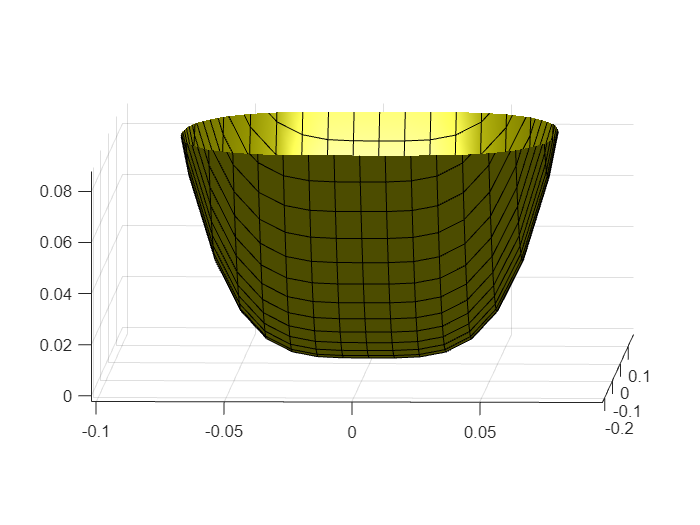

[x,y]=meshgrid(-0.5:0.01:0.5);%创建一个二维网格，x 和 y 分别取自 -0.5 到 0.5，间隔为 0.01

z1=(boat.D/boat.HW^4)*x.^4+(boat.D/boat.HL^2)*y.^2;%计算 z1 的值，根据给定的公式计算得到。其中，boat.D、boat.HW 和 boat.HL 是船体的参数，^ 表示乘方运算，.^ 表示对矩阵中的每个元素进行乘方
z2=tand(boat.theta).*x+0.16+y.*0;%计算 z2 的值，根据给定的公式计算得到。其中，tand() 函数计算角度的正切值，boat.theta 是船体的倾斜角度
surf(x,y,z1,'FaceColor','yellow')% 绘制 z1 的曲面图，并设置曲面的颜色为黄色
hold on%保持当前图形，并在后续绘图时不清除当前图形
surf(x,y,z2)%绘制 z2 的曲面图
% alpha(.6)
% surf(x,y,z,'FaceColor','red','EdgeColor','none')
camlight left; lighting phong%设置光源和光照效果
axis([-0.1 0.1 -0.2 0.2 0 0.09])%设置坐标轴的范围
daspect([0.1 0.1 0.1])%设置坐标轴的长宽比

xlim([-0.102 0.098])%设置 x 轴的显示范围
ylim([-0.226 0.174])%设置 y 轴的显示范围
zlim([-0.0023 0.0877])%设置 z 轴的显示范围

view([1.7523 3.8318])%设置视角

# 自定义函数：

function hullBoat = includeBoat(mesh,boat) %船体区域
    % 描绘出像乐高积木一样小船的微元，这里的 hullBoat 是三维数组，也是矩阵
    x = mesh.xgrid;   % 将微元信息赋值给 x, y 得到 微元信息 z
    y = mesh.ygrid;
    z=(boat.D/boat.HW^4)*x.^4+(boat.D/boat.HL^2)*y.^2;
    %根据给定的船体参数和网格坐标，计算船体的几何形状，这里的公式表示了船体的几何曲面方程
%     z= -boat.HD*cosd(x*pi/boat.HW)+boat.HD + -boat.HD*cosd(y*pi/boat.HL)+boat.HD;
    %z= ((4*boat.D)./(boat.W^2+4*boat.t*boat.W)).*x.^2+((8*boat.t*boat.D)./(boat.W^2+4*boat.t*boat.D)).*abs(x)+((4*boat.D)./(boat.L^2)).*y.^2;   % 曲面方程
    hullBoat = mesh.zgrid > z;
    %根据网格的 z 坐标和船体的几何形状，生成一个船体区域的逻辑掩码。hullBoat 是一个与网格大小相同的三维数组，其中为船体区域的元素值为 true，其他区域的元素值为 false。
end

function hullzhongwu = includezhongwu(meshz) %重物区域
    x = meshz.xgrid;   % 将微元信息赋值给 x, y 得到 微元信息 z
    z = meshz.zgrid;
    t = x.^2+(z-0.04).^2;   % 曲面方程
    hullzhongwu = t < 0.0004; 
end

function hullweigan = includeweigan(meshw,weigan) %桅杆区域,船体的质心位置
    x = meshw.xgrid;   % 将微元信息赋值给 x, y 得到 微元信息 z
    y = meshw.ygrid;
    t = x.^2+y.^2;   % 曲面方程
    hullweigan = t < weigan.r^2;%weigan.r^2代表什么？
end

function hullWater = includeWater(B,theta,mesh) %吃水区域
x = mesh.xgrid;
z = tand(theta) * x + B;
    if (theta <= 90)
            hullWater = mesh.zgrid < z;
    else
            hullWater = mesh.zgrid > z;
    end
end

function hullWater = includeWaterz(B,theta,meshz) %吃水区域
x = meshz.xgrid;
z = tand(theta) * x + B;
    if (theta <= 90)
            hullWater = meshz.zgrid < z;
    else
            hullWater = meshz.zgrid > z;
    end
end

function hullWater = includeWaterw(B,theta,meshw) %吃水区域
x = meshw.xgrid;
z = tand(theta) * x + B;
    if (theta <= 90)
            hullWater = meshw.zgrid < z;
    else
            hullWater = meshw.zgrid > z;
    end
end

function COM = COM_boat(boat_M_3,mesh) %船体COM,用于计算船体的质心位置
    M = sum(boat_M_3(:));%计算船体总质量
    
    xcom = sum((sum(sum(boat_M_3 .* mesh.xgrid)))) / M;
    ycom = sum((sum(sum(boat_M_3 .* mesh.ygrid)))) / M;
    zcom = sum((sum(sum(boat_M_3 .* mesh.zgrid)))) / M; 
 
    COM = [xcom,ycom,zcom];
end

function COM = COM_zhongwu(zhongwu_M_3,meshz) %重物COM
    M = sum(zhongwu_M_3(:));
    
    xcom = sum((sum(sum(zhongwu_M_3 .* meshz.xgrid)))) / M;%将 zhongwu_M_3 与 mesh.xgrid 相乘，并对所有元素进行求和，然后除以总质量，来计算船体的质心在 x 轴上的位置。
    ycom = sum((sum(sum(zhongwu_M_3 .* meshz.ygrid)))) / M;%将 zhongwu_M_3 与 mesh.ygrid 相乘，并对所有元素进行求和，然后除以总质量，来计算船体的质心在 y 轴上的位置。
    zcom = sum((sum(sum(zhongwu_M_3 .* meshz.zgrid)))) / M;%将 zhongwu_M_3 与 mesh.zgrid 相乘，并对所有元素进行求和，然后除以总质量，来计算船体的质心在 z 轴上的位置。
 
    COM = [xcom,ycom,zcom];%质心位置的向量
end

function COM = COM_weigan(weigan_M_3,meshw) %桅杆COM
    M = sum(weigan_M_3(:));
    
    xcom = sum((sum(sum(weigan_M_3 .* meshw.xgrid)))) / M;
    ycom = sum((sum(sum(weigan_M_3 .* meshw.ygrid)))) / M;
    zcom = sum((sum(sum(weigan_M_3 .* meshw.zgrid)))) / M; 
 
    COM = [xcom,ycom,zcom];
end

function COB = COB_boat(boatwater_M_3,mesh) %船体COB，计算船体浸没部分的中心重力位置
    M = sum(boatwater_M_3(:));%计算浸没部分的总质量，通过对 boatwater_M_3 中的所有元素进行求和
    
    xcom = sum((sum(sum(boatwater_M_3 .* mesh.xgrid)))) / M;%计算浸没部分的中心重力在 x 轴上的位置。将 boatwater_M_3 与 mesh.xgrid 相乘，并对所有元素进行求和，然后除以总质量
    ycom = sum((sum(sum(boatwater_M_3 .* mesh.ygrid)))) / M;
    zcom = sum((sum(sum(boatwater_M_3 .* mesh.zgrid)))) / M; 
 
    COB = [xcom,ycom,zcom];%中心重力位置的向量
end

function COB = COB_zhongwu(zhongwuwater_M_3,meshz) %重物COB
    M = sum(zhongwuwater_M_3(:));
    
    xcom = sum((sum(sum(zhongwuwater_M_3 .* meshz.xgrid)))) / M;
    ycom = sum((sum(sum(zhongwuwater_M_3 .* meshz.ygrid)))) / M;
    zcom = sum((sum(sum(zhongwuwater_M_3 .* meshz.zgrid)))) / M; 
 
    COB = [xcom,ycom,zcom];
end

function COB = COB_weigan(weiganwater_M_3,meshw) %桅杆COB
    M = sum(weiganwater_M_3(:));
    
    xcom = sum((sum(sum(weiganwater_M_3 .* meshw.xgrid)))) / M;
    ycom = sum((sum(sum(weiganwater_M_3 .* meshw.ygrid)))) / M;
    zcom = sum((sum(sum(weiganwater_M_3 .* meshw.zgrid)))) / M; 
 
    COB = [xcom,ycom,zcom];
end